# Planteamiento de la cinemática de posicion y velocidad para un robot Dofbot

## Resumen

Se presenta el planteamiento de la cinemática de la posición y velocidad del robot serial Dofbot de cinco grados de libertad. El modelo cinemático  planteado es mediente una solución geometrica del robot. 

## Definición de las funciones 

Matriz de transformaciones homógeneas

%Deficición de la función de manera simbolica
syms Tij(x_i_j,y_i_j,z_i_j,gi_j,bi_j,ai_j)

%Definición de la transformación homógenea general
Tij(x_i_j,y_i_j,z_i_j,gi_j,bi_j,ai_j) = [cos(ai_j)*cos(bi_j) cos(ai_j)*sin(bi_j)*sin(gi_j)-sin(ai_j)*cos(gi_j) sin(ai_j)*sin(gi_j)+cos(ai_j)*sin(bi_j)*cos(gi_j) x_i_j; sin(ai_j)*cos(bi_j) cos(ai_j)*cos(gi_j)+sin(ai_j)*sin(bi_j)*sin(gi_j) sin(ai_j)*sin(bi_j)*cos(gi_j)-cos(ai_j)*sin(gi_j) y_i_j; -sin(bi_j) cos(bi_j)*sin(gi_j) cos(bi_j)*cos(gi_j) z_i_j; 0 0 0 1]

$$Tij(x\_i\_j, y\_i\_j, z\_i\_j, gi\_j, bi\_j, ai\_j) = \left(\begin{array}{cccc} \cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{bi}}_{j}\right) & \cos\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right)-\cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right) & \sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right)+\cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right) & x_{i,j}\\ \cos\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right) & \cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right)+\sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & \cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)-\cos\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & y_{i,j}\\ -\sin\left({\mathrm{bi}}_{j}\right) & \cos\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & \cos\left({\mathrm{bi}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right) & z_{i,j}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

## Plateamiento del modelo de la cinemática directa del robot

Para el planteamiento del modelo del robot se establece la relaciones de posición y orientación de cada eslabón al asociarlos con un sistema de referencia relativo relacionado, el cual se presenta en la siguiente figura. 

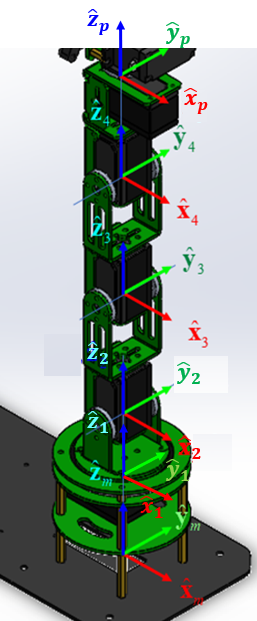

En sistema de referencia {m} está asociacdo al sistema inercial del robot y el sistema {P} está asociado con el efector final del robot en específico el punto en el cual los dedos de este pude tomar un objeto sin problemas. 

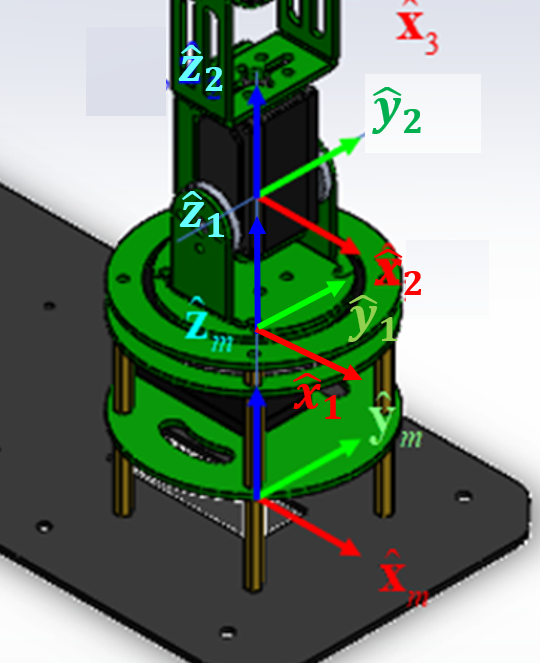

En la figura anterior se presenta los sistemas de referencia {1} y {2}, el sistema {1} está asociado con el movimiento de la cintura del robot cuya junta rotacional gira con respecto al eje ${\widehat{\mathbf{z}} }_1$ y el sistema de referecia {2} está asociado con el sistema del hombro del robot el cual gira con respecto al eje ${\widehat{y} }_2$. La matriz de tranformación homógenea que describe la relaciones de posición y de orientación entre el sistema {1} y el sistema {0} es:

## **Calculo del modelo Cinematico de la postura**

Calculo de las transformaciones de posicion entre el sistema {1} y {0}

syms z_0_1 z_1_2 theta_0_1 theta_1_2 

T_0_1 = Tij(0,0,z_0_1,0,0,theta_0_1)

$$T\_0\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{0,1}\right) & -\sin\left(\theta_{0,1}\right) & 0 & 0\\ \sin\left(\theta_{0,1}\right) & \cos\left(\theta_{0,1}\right) & 0 & 0\\ 0 & 0 & 1 & z_{0,1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

El sistema {2} está asociado a la artículación del hombro del robot y su movimiento es una rotación con respecto al eje ${\widehat{y} }_2$, la matriz de transformación de este sistema es:

T_1_2 = Tij(0,0,z_1_2,0,theta_1_2,0)

$$T\_1\_2 = \left(\begin{array}{cccc} \cos\left(\theta_{1,2}\right) & 0 & \sin\left(\theta_{1,2}\right) & 0\\ 0 & 1 & 0 & 0\\ -\sin\left(\theta_{1,2}\right) & 0 & \cos\left(\theta_{1,2}\right) & z_{1,2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

En la siguiente imagen se presenta el sistema de referencia {3} asociado al codo del robot y el sistema de referencia {4} asociado al recodo de la muñeca del robot (bend).

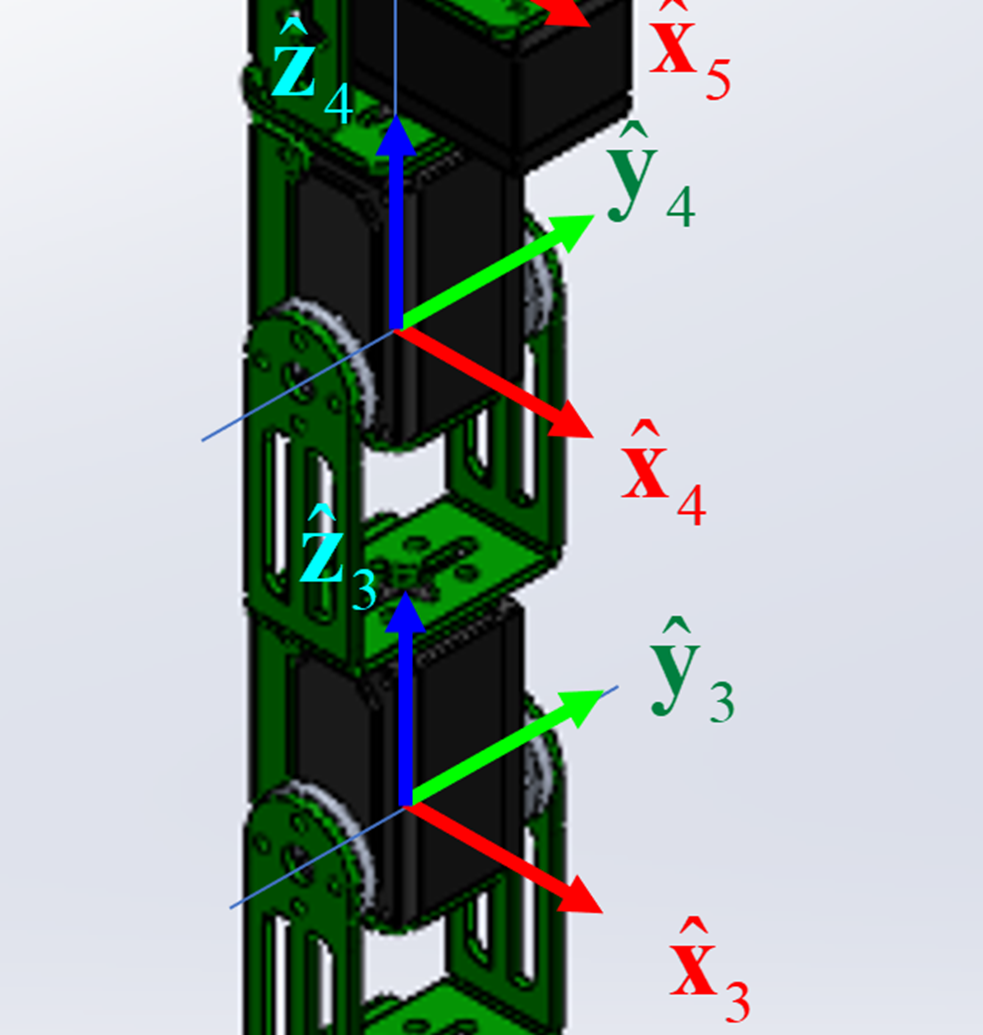

Las relaciones de posición y orientación entre el hombro y el codo del robot está dada en la matriz ${}^2{\mathbf{T}}_3$la cual describe la longitud del antebrazo del robot ${}^2z_3$ y la restricción de la junta rotación asociada con el giro sobre el eje ${\widehat{y} }_3$.

syms z_2_3 theta_2_3 z_3_4 theta_3_4

T_2_3 = Tij(0,0,z_2_3,0,theta_2_3,0)

$$T\_2\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{2,3}\right) & 0 & \sin\left(\theta_{2,3}\right) & 0\\ 0 & 1 & 0 & 0\\ -\sin\left(\theta_{2,3}\right) & 0 & \cos\left(\theta_{2,3}\right) & z_{2,3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Las relaciones de posición y orientación entre el codo y el recodo del robot está dada en la matriz ${}^3{\mathbf{T}}_4$la cual describe la longitud del antebrazo del robot ${}^3z_4$ y la restricción de la junta rotación asociada con el giro sobre el eje ${\widehat{y} }_4$.

T_3_4 = Tij(0,0,z_3_4,0,theta_3_4,0)

$$T\_3\_4 = \left(\begin{array}{cccc} \cos\left(\theta_{3,4}\right) & 0 & \sin\left(\theta_{3,4}\right) & 0\\ 0 & 1 & 0 & 0\\ -\sin\left(\theta_{3,4}\right) & 0 & \cos\left(\theta_{3,4}\right) & z_{3,4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Por ultimo, la junta asocida al sistema {4} respecto al sistema {P}.

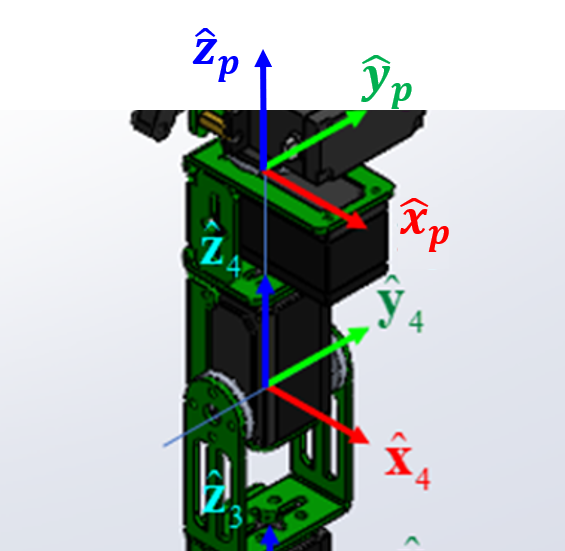

Las relaciones de posición y orientación entre el recodo y la muñeca del robot está dada en la matriz ${}^4{\mathbf{T}}_P$ la cual describe la longitud del antebrazo del robot ${}^4z_P$.

syms z_4_P  
T_4_P = Tij(0,0,z_4_P,0,0,0)

$$T\_4\_P = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & z_{4,P}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### **El modelo cinemático directo de la posición es:**

syms x_O_P

T_0_P = simplify(T_0_1*T_1_2*T_2_3*T_3_4*T_4_P)

$$T\_0\_P = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1}\,\cos\left(\theta_{0,1}\right) & -\sin\left(\theta_{0,1}\right) & \sigma_{3}\,\cos\left(\theta_{0,1}\right) & \cos\left(\theta_{0,1}\right)\,\sigma_{2}\\ \sigma_{1}\,\sin\left(\theta_{0,1}\right) & \cos\left(\theta_{0,1}\right) & \sigma_{3}\,\sin\left(\theta_{0,1}\right) & \sin\left(\theta_{0,1}\right)\,\sigma_{2}\\ -\sigma_{3} & 0 & \sigma_{1} & z_{0,1}+z_{1,2}+z_{3,4}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\cos\left(\theta_{1,2}\right)+z_{4,P}\,\sigma_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}\right)\\ \sigma_{2}=z_{4,P}\,\sigma_{3}+z_{3,4}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\sin\left(\theta_{1,2}\right)\\ \sigma_{3}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}\right) \end{array}$$

xi_O_P = [T_0_P(1,4);T_0_P(2,4);T_0_P(3,4);T_0_P(1,1);T_0_P(2,2);T_0_P(3,3)]

$$xi\_O\_P = \begin{array}{l} \left(\begin{array}{c} \cos\left(\theta_{0,1}\right)\,\sigma_{1}\\ \sin\left(\theta_{0,1}\right)\,\sigma_{1}\\ z_{0,1}+z_{1,2}+z_{3,4}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\cos\left(\theta_{1,2}\right)+z_{4,P}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}\right)\\ \cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}\right)\,\cos\left(\theta_{0,1}\right)\\ \cos\left(\theta_{0,1}\right)\\ \cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=z_{4,P}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}\right)+z_{3,4}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\sin\left(\theta_{1,2}\right) \end{array}$$

## **Modelo cinematico directo de las velocidades**

$\dot{{}^O{\xi }_P} =J_{\theta } \left(q\right)\dot{\;q}$c  

syms J_theta q_dot theta_dot_0_1 theta_dot_1_2 theta_dot_2_3 theta_dot_3_4 theta_dot_4_5

J_theta

$$J\_theta = J_{\theta }$$

J_theta = jacobian(xi_O_P,[theta_0_1,theta_1_2,theta_2_3,theta_3_4])

$$J\_theta = \begin{array}{l} \left(\begin{array}{cccc} -\sin\left(\theta_{0,1}\right)\,\sigma_{2} & \cos\left(\theta_{0,1}\right)\,\sigma_{3} & \cos\left(\theta_{0,1}\right)\,\left(\sigma_{7}+z_{4,P}\,\sigma_{6}\right) & z_{4,P}\,\sigma_{6}\,\cos\left(\theta_{0,1}\right)\\ \cos\left(\theta_{0,1}\right)\,\sigma_{2} & \sin\left(\theta_{0,1}\right)\,\sigma_{3} & \sin\left(\theta_{0,1}\right)\,\left(\sigma_{7}+z_{4,P}\,\sigma_{6}\right) & z_{4,P}\,\sigma_{6}\,\sin\left(\theta_{0,1}\right)\\ 0 & -z_{4,P}\,\sigma_{5}-\sigma_{4}-z_{2,3}\,\sin\left(\theta_{1,2}\right) & -z_{4,P}\,\sigma_{5}-\sigma_{4} & -z_{4,P}\,\sigma_{5}\\ -\sigma_{6}\,\sin\left(\theta_{0,1}\right) & \sigma_{1} & \sigma_{1} & \sigma_{1}\\ -\sin\left(\theta_{0,1}\right) & 0 & 0 & 0\\ 0 & -\sigma_{5} & -\sigma_{5} & -\sigma_{5} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\sigma_{5}\,\cos\left(\theta_{0,1}\right)\\ \sigma_{2}=z_{4,P}\,\sigma_{5}+\sigma_{4}+z_{2,3}\,\sin\left(\theta_{1,2}\right)\\ \sigma_{3}=\sigma_{7}+z_{2,3}\,\cos\left(\theta_{1,2}\right)+z_{4,P}\,\sigma_{6}\\ \sigma_{4}=z_{3,4}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)\\ \sigma_{5}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}\right)\\ \sigma_{6}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}\right)\\ \sigma_{7}=z_{3,4}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right) \end{array}$$


$$J^+ ={\left(J^T J\right)}^{-1} J^T$$


J_T = J_theta.'

$$J\_T = \begin{array}{l} \left(\begin{array}{cccccc} -\sin\left(\theta_{0,1}\right)\,\sigma_{2} & \cos\left(\theta_{0,1}\right)\,\sigma_{2} & 0 & -\sigma_{6}\,\sin\left(\theta_{0,1}\right) & -\sin\left(\theta_{0,1}\right) & 0\\ \cos\left(\theta_{0,1}\right)\,\sigma_{3} & \sin\left(\theta_{0,1}\right)\,\sigma_{3} & -z_{4,P}\,\sigma_{5}-\sigma_{4}-z_{2,3}\,\sin\left(\theta_{1,2}\right) & \sigma_{1} & 0 & -\sigma_{5}\\ \cos\left(\theta_{0,1}\right)\,\left(\sigma_{7}+z_{4,P}\,\sigma_{6}\right) & \sin\left(\theta_{0,1}\right)\,\left(\sigma_{7}+z_{4,P}\,\sigma_{6}\right) & -z_{4,P}\,\sigma_{5}-\sigma_{4} & \sigma_{1} & 0 & -\sigma_{5}\\ z_{4,P}\,\sigma_{6}\,\cos\left(\theta_{0,1}\right) & z_{4,P}\,\sigma_{6}\,\sin\left(\theta_{0,1}\right) & -z_{4,P}\,\sigma_{5} & \sigma_{1} & 0 & -\sigma_{5} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\sigma_{5}\,\cos\left(\theta_{0,1}\right)\\ \sigma_{2}=z_{4,P}\,\sigma_{5}+\sigma_{4}+z_{2,3}\,\sin\left(\theta_{1,2}\right)\\ \sigma_{3}=\sigma_{7}+z_{2,3}\,\cos\left(\theta_{1,2}\right)+z_{4,P}\,\sigma_{6}\\ \sigma_{4}=z_{3,4}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)\\ \sigma_{5}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}\right)\\ \sigma_{6}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}\right)\\ \sigma_{7}=z_{3,4}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right) \end{array}$$

J_R = J_T*J_theta

simplify(inv(J_R))

%Lamentablemente no fue posible calcular la inversa porque nuestro equipo
%de trabajo no tenia las caracteristicas necesarias para poder calcular
%esta operacion, se intento utilizar el servidor online pero nunca termino
%de ejecutarse la operacion.


$$\begin{array}{l}
\dot{\;\dot{q} =J_{\theta } \left(q\right)} +\dot{{}^O{\xi }_P} \\

\end{array}$$


q_dot
q_dot=[theta_dot_0_1,theta_dot_1_2, theta_dot_2_3, theta_dot_3_4]